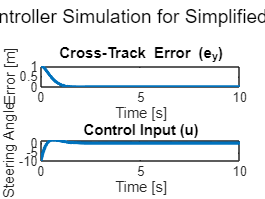

% LQR Controller Simulation for a Simplified System

% System Definition
A = [0, 1; 
     0, 0];  % State matrix (controllable)
B = [0; 
     1];     % Input matrix

% Check Controllability
Ctrb = ctrb(A, B);
if rank(Ctrb) < size(A, 1)
    error('The system (A, B) is not controllable.');
end

% Cost Matrices
Q = diag([10, 1]); % Penalize position error and velocity
R = 0.1;           % Penalize control effort

% Solve the Algebraic Riccati Equation for P
[P, ~, ~] = care(A, B, Q, R);

% Compute the LQR Gain Matrix K
K = R \ (B' * P);

% Time Vector
T = 0:0.01:10; % Simulation time (0 to 10 sec, 0.01 step)
dt = 0.01;

% Initial Conditions
x = [1; 0]; % Initial state [e_y (position error), \dot{e}_y (velocity error)]
u = 0;      % Initial control input

% Preallocate for Data
X = zeros(2, length(T));
U = zeros(1, length(T));

% Simulation Loop
for k = 1:length(T)
    % Control Law: u = -Kx
    u = -K * x;
    
    % Store Data
    X(:, k) = x;
    U(k) = u;

    % System Dynamics: x_dot = A*x + B*u
    x_dot = A * x + B * u;

    % Update State with Euler Integration
    x = x + x_dot * dt;
end

% Plot Results
figure;

subplot(2, 1, 1);
plot(T, X(1, :), 'LineWidth', 2);
title('Cross-Track Error (e_y)');
xlabel('Time [s]');
ylabel('Error [m]');

subplot(2, 1, 2);
plot(T, U, 'LineWidth', 2);
title('Control Input (u)');
xlabel('Time [s]');
ylabel('Steering Angle');

sgtitle('LQR Controller Simulation for Simplified System');